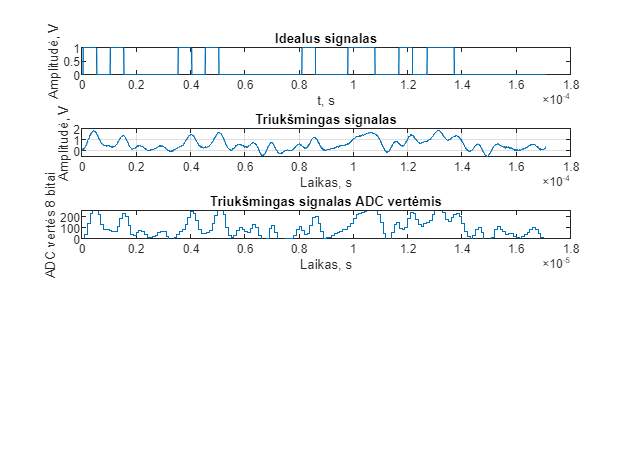

fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

dataSend = "101001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1);

N = length(idealSignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(5, 1, 1)
plot(t, idealSignal)
xlabel('t, s')
ylabel('Amplitudė, V')
title('Idealus signalas')

%Filtro š

subplot(5, 1, 2)
plot(t, noisySignal)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Triukšmingas signalas')
grid on

subplot(5, 1, 3)
N = length(ADCsignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);
stairs(t, ADCsignal)
ylabel('ADC vertės 8 bitai')
xlabel('Laikas, s')
title('Triukšmingas signalas ADC vertėmis')
ylim([0, 255])


%{
syms V
INLideal = ADCbits/ADCmax * V;
INLreal = ADCbits/ADCmax * V*(1*V);

V = 1.5/2
subs(INLideal)
INLsignal = []
for i = 1: length(noisySignal)
    V = noisySignal(i);
    reiksme = round(subs(INLreal));
    INLsignal = [INLsignal, reiksme];
end
subplot(5, 1, 4)
stairs(n, INLsignal)
ylabel('ADC vertės 8 bitai')
xlabel('Laikas, s')
title('ADC su INL')
ylim([0, 255])

figure
syms V
fplot(V, INLideal)
ylabel('ADC vertes')
xlabel('Itampa, V')
title('Integral non linearity funkcija')
ylim([0, 255])
xlim([0, 1.5])
hold on
fplot(V, INLreal)
hold off;
legend('Ideali', 'Reali')
%}


%Irasyti failaa
%{
testVoltage = fopen('testVoltage.txt','w');
preambuleVoltage = fopen('idealPreambuleVoltage.txt','w');
idealOne = fopen('idealOneVoltage.txt','w');
idealZero = fopen('idealZeroVoltage.txt','w');
for i = 1:length(ADCsignal)
    temp = dec2bin(ADCsignal(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end
for i = 1:length(ADCpreambule)
    temp = dec2bin(ADCpreambule(i), 8);
    fprintf(preambuleVoltage,'%s\n',temp);
end
for i = 1:length(idealOne)
    temp = dec2bin(idealOne(i), 8);
    fprintf(idealOne,'%s\n',temp);
    temp = dec2bin(idealZero(i), 8);
    fprintf(idealZero,'%s\n',temp);
end
fclose(testVoltage);
fclose(preambuleVoltage);
fclose(idealOne);
fclose(idealZero);
%}

%{
funkcijuFailas = fopen('Conv_func_data.mif','w');
duomenisIrasyti = [ADCpreambule, idealOne, idealZero, idealZero, idealOne, idealZero, idealZero, idealOne, idealOne]; %Praembule, idealOne, idealZero

fprintf(funkcijuFailas, "WIDTH=8;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=UNS;\nCONTENT BEGIN \n", length(duomenisIrasyti));

for i = 1:length(duomenisIrasyti)
    %temp = dec2bin(duomenisIrasyti(i), 8);
    %fprintf(funkcijuFailas,'%s\n',temp);
    fprintf(funkcijuFailas,'%i : %i;\n',i-1, duomenisIrasyti(i));
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);
%}

testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(ADCsignal)
    temp = dec2bin(ADCsignal(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end





%figure
%stairs(t, 3*ADCsignal, 'LineWidth',2)
%hold on
%konvoliucija1 = conv(ADCsignal, idealOne);
%plot(t, konvoliucija1(1:length(ADCsignal)))
%title('Koreliacija su vienetu')
%xlabel('Atskaitos, n')

%konvoliucija2 = conv(ADCsignal, idealZero);
%plot(t, konvoliucija2(1:length(ADCsignal)))
%title('Koreliacija su nuliu')
%xlabel('Laikas ,t')
%{
konvoliucija3 = conv(ADCsignal, onezero);
stairs(t, konvoliucija3(1:length(ADCsignal)))

konvoliucija4 = conv(ADCsignal, zeroone);
stairs(t, konvoliucija4(1:length(ADCsignal)))

konvoliucija5 = conv(ADCsignal, zerozero);
stairs(t, konvoliucija5(1:length(ADCsignal)))

konvoliucija6 = conv(ADCsignal, oneone);
stairs(t, konvoliucija6(1:length(ADCsignal)))

xline(velinimasPreambules);
xline(velinimasPreambules+3E-6);
xline(velinimasPreambules+3E-6+2E-6);
xline(velinimasPreambules+3E-6+4E-6);
xline(velinimasPreambules+3E-6+6E-6);

%xline(117/fdiskret, 'color','green');
%xline(138/fdiskret, 'color','green');
%xline(159/fdiskret, 'color','green');

legend("idealSignal", "10", "01", "00", "11")

hold off
%}



%IMIMAS IS MODELSIMO
%{
msfile = fopen('list.txt','r');
pliusas = char(43);
formatSpec = ['%d %d %d %d %d %d %d %d'];

msdata = fscanf(msfile,formatSpec, [8 inf]);

fclose(msfile);

% time +4 arrIndex  adcout 00 01 10 11

for i = 1:length(msdata(4, :))
    %msdata(4, i) = bin2dec(string(msdata(4, i)));
end

figure
stairs(msdata(5, :))
hold on
stairs(msdata(7, :))
hold off

stairs(konvoliucija5)
hold on
stairs(konvoliucija3)
hold off
figure
stairs(msdata(4, :)*10, 'LineWidth',2)
hold on
stairs(msdata(5, :))
stairs(msdata(6, :))
stairs(msdata(7, :))
stairs(msdata(8, :))
legend("OG", "00", "01", "10", "11")

figure

stairs(msdata(5, :))
hold on
legend( "FPGA 00", "Matlabo 00")
hold off
%}


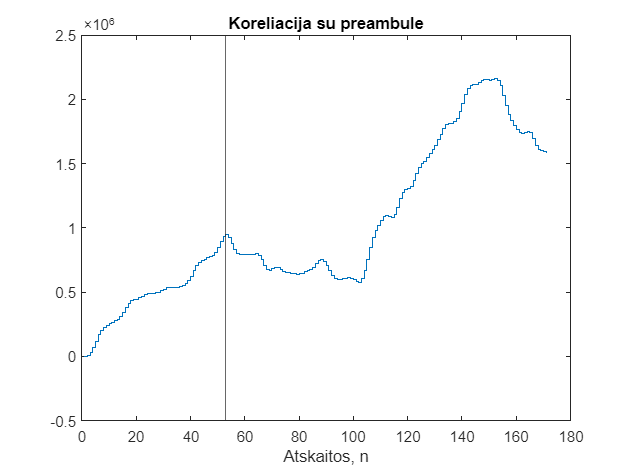

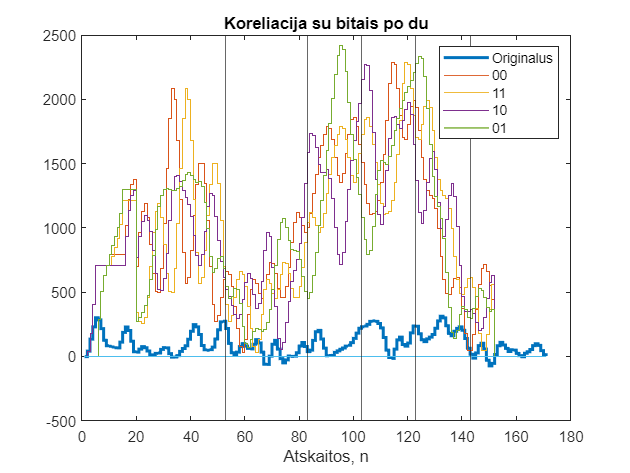

SignaluKonvoliucija(ADCsignal, ADCpreambule, 1);

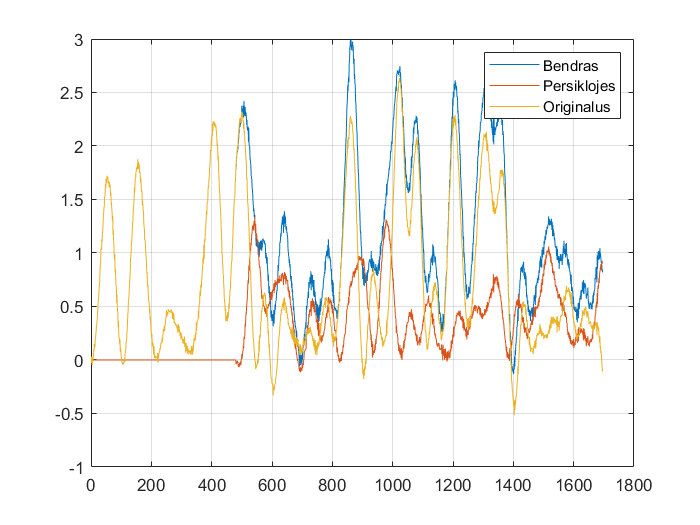

%Generuoja patikimuma nuo triuksmo
clear all
dataSend = "101001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 0.5);

randomDelay = round(100+1000*rand(1));
susceilintas = [zeros(1, randomDelay), noisySignal2];
susceilintas = susceilintas(1:length(noisySignal));
suPersidengimuSignalas = noisySignal + susceilintas;

n = 1:length(suPersidengimuSignalas);
figure
plot(n, suPersidengimuSignalas)
hold on
plot(n, susceilintas)
plot(n, noisySignal)
hold off
legend("Bendras", "Persiklojes", "Originalus");
grid on;


SignaluKonvoliucija(suPersidengimuSignalas(1:10:length(suPersidengimuSignalas)), ADCpreambule, 0);
signaloSnr = snr(noisySignal, susceilintas)

signaloSnr = 6.9929

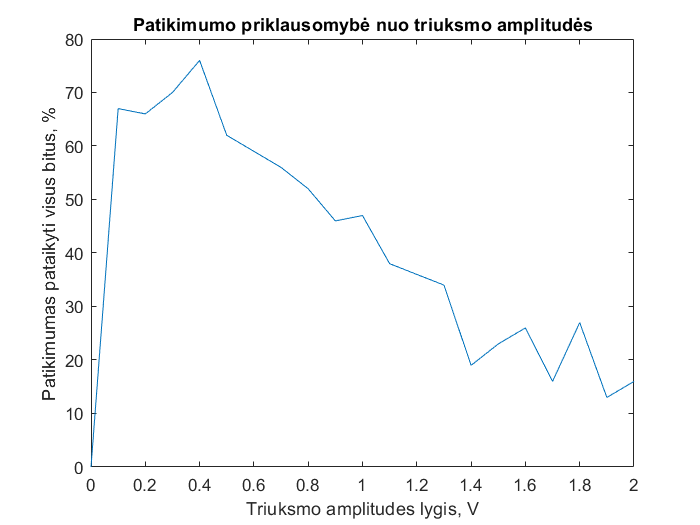

amplDuomenys = [0];
amplX = [0];
generuotiBandymu = 100;
for ampl = 0.1:0.1:2
    geri = 0;
    for i = 1:generuotiBandymu
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
        [idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, ampl);

        randomDelay = round(100+1000*rand(1));
        susceilintas = [zeros(1, randomDelay), noisySignal2];
        susceilintas = susceilintas(1:length(noisySignal));
        suPersidengimuSignalas = noisySignal + susceilintas;
        suPersidengimuSignalas = suPersidengimuSignalas(1:10:length(suPersidengimuSignalas));
        suPersidengimuSignalas = [suPersidengimuSignalas, zeros(1, 200)];

        [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(suPersidengimuSignalas, ADCpreambule, 0);
    
        veikia = 1;
        for y = 1:3
            [a, b] = max(konvSignalai(:, konvLaikai(y)));
            if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
                veikia = 0;
            end
        end
        if(veikia == 1)
            geri = geri + 1;
        end
        %duomenys(b) = duomenys(b) + 1;
        %FindMax(konvSignalai(:, konvLaikai(1)), konvPavadinimai)
    end
    amplDuomenys = [amplDuomenys, geri/generuotiBandymu*100];
    amplX = [amplX, ampl];
end

figure
plot(amplX, amplDuomenys)
xlabel("Triuksmo amplitudes lygis, V")
ylabel("Patikimumas pataikyti visus bitus, %")
title("Patikimumo priklausomybė nuo triuksmo amplitudės")

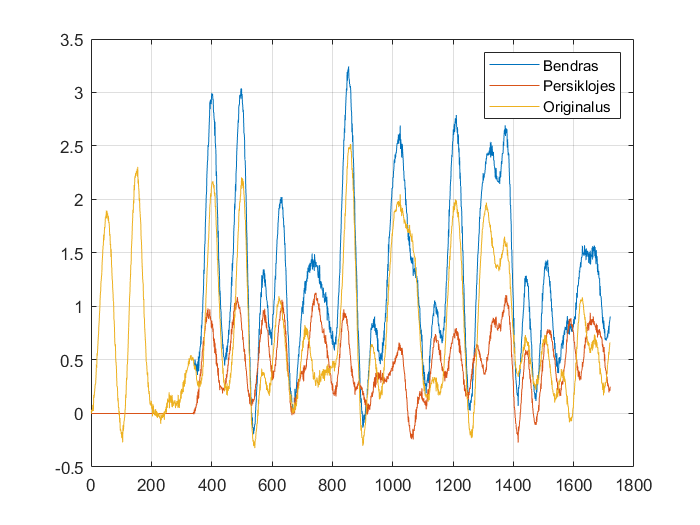

%Generuoja patikimuma nuo triuksmo
clear all
dataSend = "101001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 0.5);

randomDelay = round(100+1000*rand(1));
susceilintas = [zeros(1, randomDelay), noisySignal2];
susceilintas = susceilintas(1:length(noisySignal));
suPersidengimuSignalas = noisySignal + susceilintas;

n = 1:length(suPersidengimuSignalas);
figure
plot(n, suPersidengimuSignalas)
hold on
plot(n, susceilintas)
plot(n, noisySignal)
hold off
legend("Bendras", "Persiklojes", "Originalus");
grid on;


SignaluKonvoliucija(suPersidengimuSignalas(1:10:length(suPersidengimuSignalas)), ADCpreambule, 0);
signaloSnr = snr(noisySignal, susceilintas)

signaloSnr = 5.8141

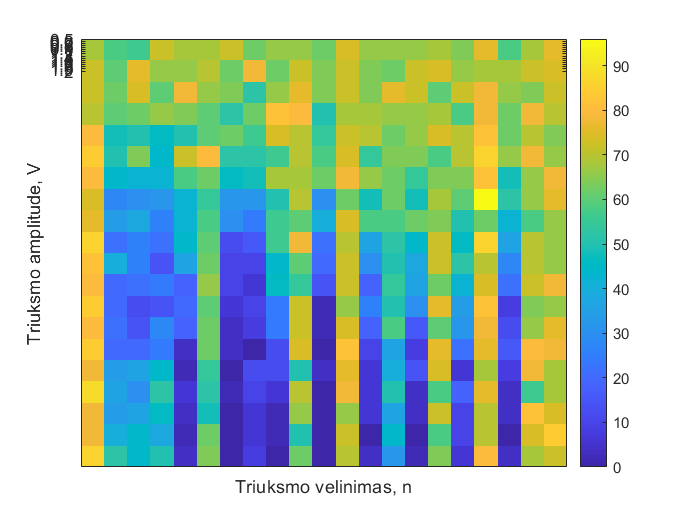

%{
generuotiBandymu = 50;
irasyti = [];
for ampl = 0.1:0.1:2
    temp = [];
    for t = 0:75:1500
        geri = 0;
        for x = 1:generuotiBandymu
            [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
            [idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, ampl);
    
            %randomDelay = round(100+1000*rand(1));
            randomDelay = t;
            susceilintas = [zeros(1, randomDelay), noisySignal2, zeros(1, 500)];
            susceilintas = susceilintas(1:length(noisySignal));
            suPersidengimuSignalas = noisySignal + susceilintas;
            suPersidengimuSignalas = suPersidengimuSignalas(1:10:length(suPersidengimuSignalas));
            suPersidengimuSignalas = [suPersidengimuSignalas, zeros(1, 200)];
    
            [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(suPersidengimuSignalas, ADCpreambule, 0);
        
            veikia = 1;
            for y = 1:3
                [a, b] = max(konvSignalai(:, konvLaikai(y)));
                if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
                    veikia = 0;
                end
            end
            if(veikia == 1)
                geri = geri + 1;
            end
            %duomenys(b) = duomenys(b) + 1;
            %FindMax(konvSignalai(:, konvLaikai(1)), konvPavadinimai)
        end
        temp = [temp, geri/generuotiBandymu*100];
        %amplDuomenys = [amplDuomenys, geri/generuotiBandymu*100];
        %
    end
    irasyti = [irasyti; temp];
end

figure
imagesc(irasyti)
yticks(0.1:0.1:2)
xticks(0:50:1500)
ylabel("Triuksmo amplitude, V")
xlabel("Triuksmo velinimas, n")
colorbar

%}
%plot(amplX, amplDuomenys)
%xlabel("Triuksmo amplitudes lygis, V")
%ylabel("Patikimumas pataikyti visus bitus, %")
%title("Patikimumo priklausomybė nuo triuksmo amplitudės")


%Gneruoja patikimuma dalyku
dataSend = "101001";
geri = 0

geri = 0

for i = 1:100
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1);
    [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(ADCsignal, ADCpreambule, 0);
    konvSignalai = [konvSignalai, zeros(4, 200)];

    veikia = 1;
    for y = 1:3
        [a, b] = max(konvSignalai(:, konvLaikai(y)));
        if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
            veikia = 0;
        end
    end
    if(veikia == 1)
        geri = geri + 1;
    end
end
geri

geri = 62

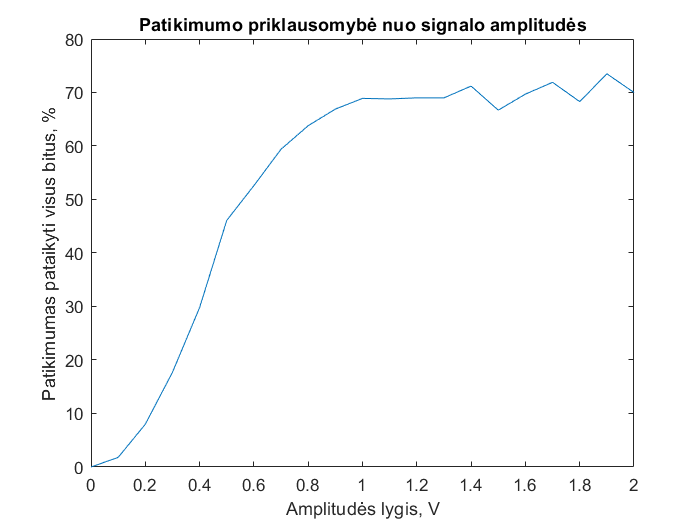

%Gneruoja patikimuma nuo amplitudes
dataSend = "101001";
amplDuomenys = [0];
amplX = [0];
generuotiBandymu = 1000;
for ampl = 0.1:0.1:2
    geri = 0;
    for i = 1:generuotiBandymu
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, ampl);
        [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(ADCsignal, ADCpreambule, 0);
        konvSignalai = [konvSignalai, zeros(4, 200)];
    
        veikia = 1;
        for y = 1:3
            [a, b] = max(konvSignalai(:, konvLaikai(y)));
            if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
                veikia = 0;
            end
        end
        if(veikia == 1)
            geri = geri + 1;
        end
        %duomenys(b) = duomenys(b) + 1;
        %FindMax(konvSignalai(:, konvLaikai(1)), konvPavadinimai)
    end
    amplDuomenys = [amplDuomenys, geri/generuotiBandymu*100];
    amplX = [amplX, ampl];
end

figure
plot(amplX, amplDuomenys)
xlabel("Amplitudės lygis, V")
ylabel("Patikimumas pataikyti visus bitus, %")
title("Patikimumo priklausomybė nuo signalo amplitudės")

function y = GenerateConv(a, b)
    y = zeros(1, length(a));
    for i = 1:length(a)-length(b)
        if(i < length(b))
            testArr = [b(1:i), zeros(1, length(a)- i)];
        else
            testArr = [zeros(1, i), b, zeros(1, length(a)-length(b) - i)];
        end
        length(testArr);
        y(i) = sum(a.*testArr);
    end
end

function [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(pagrindinisSignalas, preambulesSignalas, grafikai)
    fdiskret = 10E6;
    tdiskret = 1/fdiskret;
    
    tprescaler = 10;
    ikiKurIeskotiPreambules = 75;
    
    idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
    idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

    konvoliucijaPreambule = conv(pagrindinisSignalas, preambulesSignalas);
    [amplitiude, velinimasPreambulesN] = max(konvoliucijaPreambule(1:ikiKurIeskotiPreambules));
    velinimasPreambules = velinimasPreambulesN / fdiskret;
    
    if grafikai == 1
        n = 1:length(pagrindinisSignalas);
        t = n/fdiskret;
        
        figure
        stairs(n, konvoliucijaPreambule(1:length(pagrindinisSignalas)))
        xline(velinimasPreambulesN);
        title('Koreliacija su preambule')
        xlabel('Atskaitos, n')
    end

    n11 = GenerateConv(pagrindinisSignalas, [idealOne(1:10:length(idealOne)), idealOne(1:10:length(idealOne))]);
    n00 = GenerateConv(pagrindinisSignalas, [idealZero(1:10:length(idealZero)), idealZero(1:10:length(idealZero))]);
    n01 = GenerateConv(pagrindinisSignalas, [idealZero(1:10:length(idealZero)), idealOne(1:10:length(idealOne))]);
    n10 = GenerateConv(pagrindinisSignalas, [idealOne(1:10:length(idealOne)), idealZero(1:10:length(idealZero))]);
    np = GenerateConv(pagrindinisSignalas, preambulesSignalas);
    
    if grafikai == 1
        figure
        stairs(pagrindinisSignalas, 'LineWidth',2)
        hold on
        stairs(n00)
        stairs(n11)
        stairs(n10)
        stairs(n01)
        stairs(np)
        
        
        
        xline((velinimasPreambules)*fdiskret);
        xline((velinimasPreambules+3E-6)*fdiskret);
        xline((velinimasPreambules+3E-6+2E-6)*fdiskret);
        xline((velinimasPreambules+3E-6+4E-6)*fdiskret);
        xline((velinimasPreambules+3E-6+6E-6)*fdiskret);
        
        legend("Originalus", "00", "11", "10", "01")
        title('Koreliacija su bitais po du')
        xlabel('Atskaitos, n')
        hold off
    end

    konvSignalai = [n11; n00; n10; n01];
    konvPavadinimai = ["11"; "00"; "10"; "01"];
    konvLaikai = [round((velinimasPreambules+3E-6)*fdiskret), round((velinimasPreambules+3E-6+2E-6)*fdiskret),round((velinimasPreambules+3E-6+4E-6)*fdiskret), round((velinimasPreambules+3E-6+6E-6)*fdiskret)];
end

function output = DiscretizeSignal(input)
    output = input(1:10:length(input));
end

function output = SteppSignal(input)
    ADCmax = 1.5;
    ADCbits = pow2(8)-1;
    output = round(input / ADCmax*ADCbits); %1.5V Vref
    for i = 1: length(input)
        if(input(i) > ADCbits)
            input(i) = ADCbits;
        elseif(input(i) < 0)
            input(i) = 0;
        end
    end
end

function [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(bits, A)
    fdiskret = 10E6;
    tdiskret = 1/fdiskret;
    
    tprescaler = 10;
        
    idealOne = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
    idealZero = A*[zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

    idealPreambule = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

    idealSignal = [zeros(1, 5), idealPreambule, zeros(1, round(3E-6/tdiskret*tprescaler))];
    
    for i = 1 : strlength(bits)
        random = round(1 + 10*randn(1));
        if(bits{1}(i) == "0")
            if(random > 0)
                idealSignal = [idealSignal, zeros(1, random), idealZero];
            elseif(random < 0)
                idealSignal = [idealSignal, idealZero(abs(random):length(idealZero))];
            else
                idealSignal = [idealSignal, idealZero];
            end
            
        else
            if(random > 0)
                idealSignal = [idealSignal, zeros(1, random), idealOne];
            elseif(random < 0)
                idealSignal = [idealSignal, idealOne(1:(length(idealOne)-abs(random)))];
            else
                idealSignal = [idealSignal, idealOne];
            end
            
        end
    end

    idealSignal = [idealSignal, zeros(1, round(3E-6/tdiskret*tprescaler))];

    %Noisy signalas
    load 'FiltroKoef.mat';
    noisySignal = filter(Hd, idealSignal);
    %Triuksmo generavimas
    vid = 0.3;
    std = 1.2;
    %triuksmas = vid + std*randn(1, N);
    triuksmas = vid + std*randn(1, length(noisySignal));
    triuksmasFiltruotas = filter(Hd, triuksmas);
    noisySignal = noisySignal + triuksmasFiltruotas;


    %Diskretizuotas
    discretizedSignal = DiscretizeSignal(noisySignal);

    %ADC
    ADCsignal = SteppSignal(discretizedSignal);
    ADCpreambule = SteppSignal(idealPreambule);

    return 
end

function ats = FindMax(reiksmes, pavadinimas)
    [~, b] = max(reiksmes);
    ats = pavadinimas(b);
end